# Adding Boundary Conditions to Galerkin's Method for Function Approximation

clear
close all

x = sym( "x", "real" );
f(x) = sin( x )

$$f(x) = \sin\left(x\right)$$

domain = [0, 1];

y0 = f( domain(1) )

$$y0 = 0$$

y1 = f( domain(2) )

$$y1 = \sin\left(1\right)$$


int( dirac( x - domain(1) ) * f(x), [-inf, inf] )

$$ans = 0$$

int( dirac( x - domain(2) ) * f(x), [-inf, inf] )

$$ans = \sin\left(1\right)$$

clear
close all

x = sym( "x", "real" );
target_fun = sin( pi * x ) ^ 2;
domain = [-1, 1];
degree = 6;

[u, M, F, N, d] = ScalarProjection( "Legendre", target_fun, degree, domain );
l2_error = ComputeL2Error( target_fun, simplify( u ), domain );
l2_error = vpa( simplify( abs( l2_error ) ), 16 )

$$l2\_error = 0.0822770571387796$$

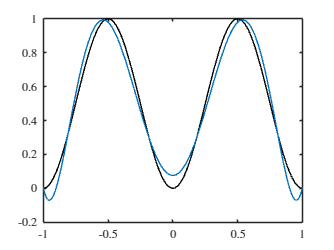


figure
hold on
fplot( target_fun, domain, color="k" )
fplot( u, domain, SeriesIndex=1 )

## Part 2

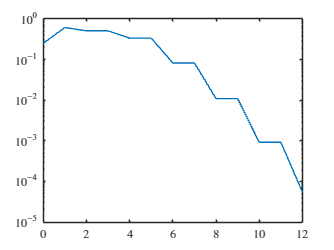

clear
close all

x = sym( "x", "real" );
target_fun = sin( pi * x ) ^ 2;
domain = [-1, 1];
boundary_tol = 1e-2;
penalty = 1e2;

degree = (0:12);
l2_error = zeros( size( degree ) );
for p = 1 : length( degree )
    u = ScalarProjection( "Monomial", target_fun, degree(p), domain );
    l2_error(p) = double( vpa( simplify( ComputeL2Error( target_fun, simplify( u ), domain ), 16 ) ) );
end

figure
semilogy( degree, l2_error )

clear
x = sym("x");
domain = [-0.5 0.2];
f(x) = real( x^x )

$$f(x) = \mathrm{real}\left(x^{x}\right)$$


degree = 4;
[u, M, F, N, d] = ScalarProjection( "Legendre", f, degree, domain );
l2_error = ComputeL2Error( f, u, domain );
l2_error = vpa( l2_error, 8 )

$$l2\_error = 0.018788187$$

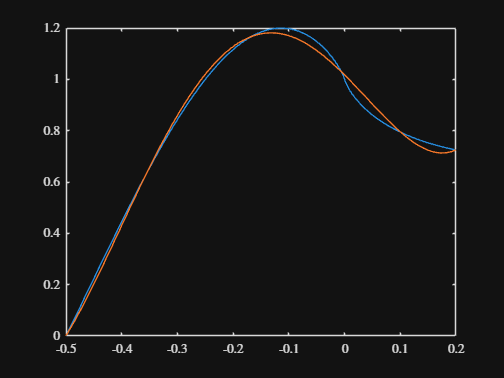


figure
hold on
fplot( f, domain )
fplot( u, domain )